# LABORATORIO 2 - SISTEMAS DE CONTROL DIGITAL

## MODELO TOERICO

Rt = 0.0054;
Ct = 2.7633;

A = -1/(Rt*Ct)

A = -67.0160

B = 44/Ct

B = 15.9230

C = 0.25

C = 0.2500

D = 0;
[num,den]= ss2tf(A,B,C,D);

systc = tf(num,den)

systc =
 
    3.981
  ---------
  s + 67.02
 
Continuous-time transfer function.



systd = c2d(systc,0.001)

systd =
 
   0.00385
  ----------
  z - 0.9352
 
Sample time: 0.001 seconds
Discrete-time transfer function.



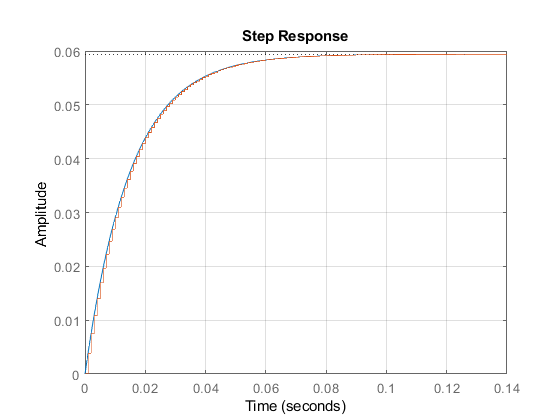

figure('Name','HORNO')
step(systc)
hold on
step(systd)
grid on

## MODELO REAL

Ymax = 5;                   %maximo voltaje de salida
Ymin = 0.625;               %voltaje a 25°c
Umax = 2;                   %maximo voltaje de entrada
Umin = 0;                   %minimo voltaje de entrada

Testa = 40;                 %tiempo de establecimiento
Ts = 1;                     %tiempo de muestreo
k = (Ymax-Ymin)/(Umax-Umin) %GANANCIA

k = 2.1875

tau = Testa / 4;            %constante de tiempo
s1 = tf('s');
sysc = k/(tau*s1+1)         %funcion de transferencia continua

sysc =
 
   2.188
  --------
  10 s + 1
 
Continuous-time transfer function.



sysd = c2d(sysc,Ts,'zoh')   %funcion de transferencia discreta

sysd =
 
    0.2082
  ----------
  z - 0.9048
 
Sample time: 1 seconds
Discrete-time transfer function.



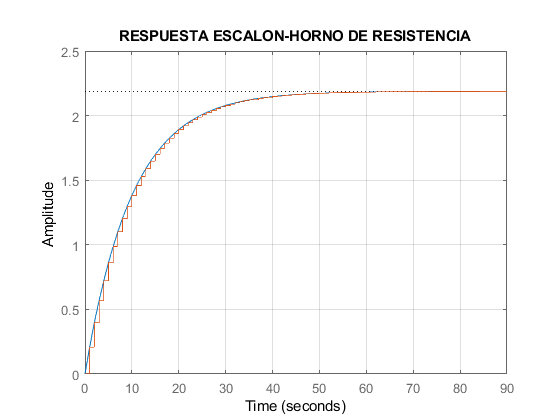

figure('Name','HORNO')
step(sysc)
hold on
step(sysd)
title('RESPUESTA ESCALON-HORNO DE RESISTENCIA')
grid on

## SISTEMA REALIMENTADO

sysrc = feedback(sysc,1)

sysrc =
 
     2.188
  ------------
  10 s + 3.188
 
Continuous-time transfer function.



sysrd = feedback(sysd,1)

sysrd =
 
    0.2082
  ----------
  z - 0.6967
 
Sample time: 1 seconds
Discrete-time transfer function.



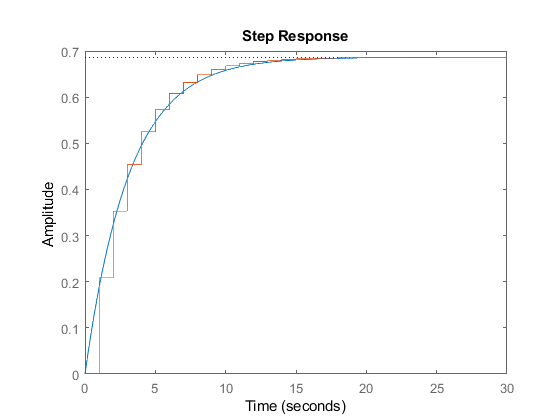

figure('Name','SISTEMA REALIMENTADO')
step(sysrc)
hold on
step(sysrd)